# Filtr cyfrowy IIR

DATA:

fs      = 16e3;
f       = 0:fs-1;
%f       = linspace(0,fs,fs)
omega   = f*2*pi;

sygnal cyfrowy:

t = 0:1/fs:1-1/fs;
csig = 1*sin(2*pi*1209*t) + 1*sin(2*pi*1272*t);

load butter.mat

importbutter()

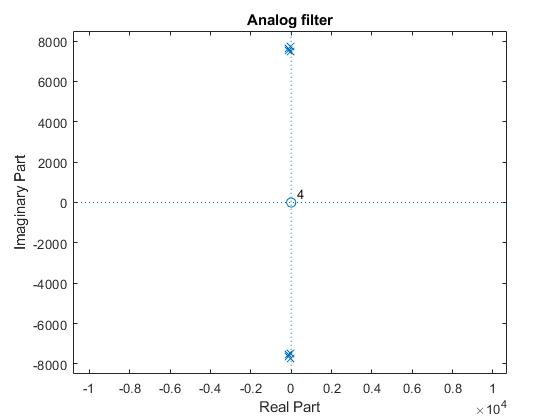

% [zb,pb,kb] = butter(n,2*pi*f,'s');
[b,a] = zp2tf(z,p,k); % z pierwiastkow na wielomian
[ha,wa]= freqs(b,a,omega);
% fvtool(b,a)


[bx,ax] = bilinear(b,a,fs);
[hx,wx] = freqz(bx,ax,f,fs);

figure
zplane(b,a)
title('Analog filter')

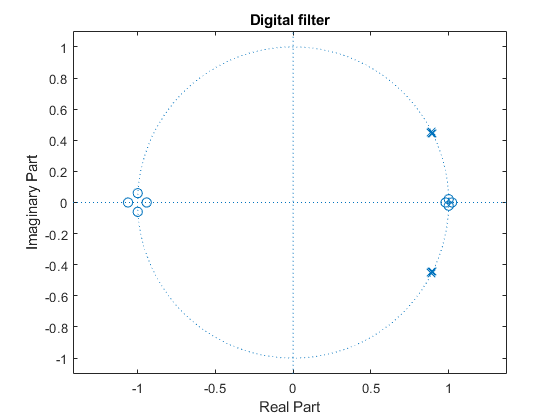


figure
zplane(bx,ax)
title('Digital filter')

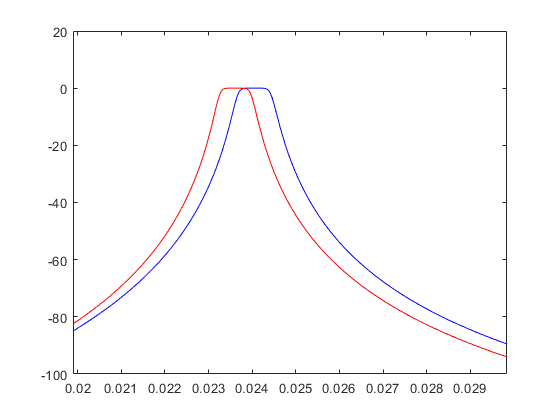


figure
plot(wx/(fs*pi),mag2db(abs(ha)),'b')
hold on 
plot(wx/(fs*pi),mag2db(abs(hx)),'r')
xlim([1000/(fs*pi) 1500/(fs*pi)]);

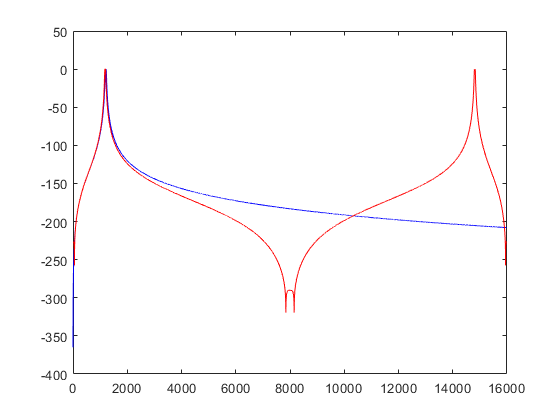


figure
plot(f,20*log10(abs(ha)),'b');
hold on
plot(f,20*log10(abs(hx)),'r');

filtracja:

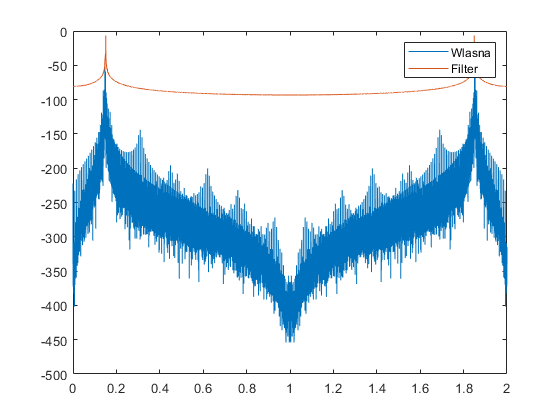

Y1 = 20*log10(fft(abs(csig)/(fs/2)));

y2 = filter(bx,ax,csig);
Y2 = 20*log10(abs(fft(y2)/(fs/2)));

Y1a = 20*log10(abs(ha .* fft(abs(csig)/(fs/2))));
Y1c = 20*log10(abs(hx .* fft(abs(csig)/(fs/2))));

ya = ifft(Y1a);
yc = ifft(Y1c);
yf = ifft(Y2);

figure
plot(wa/(fs*pi),Y1c)
hold on
plot(wa/(fs*pi),Y2)
legend({'Wlasna','Filter'})

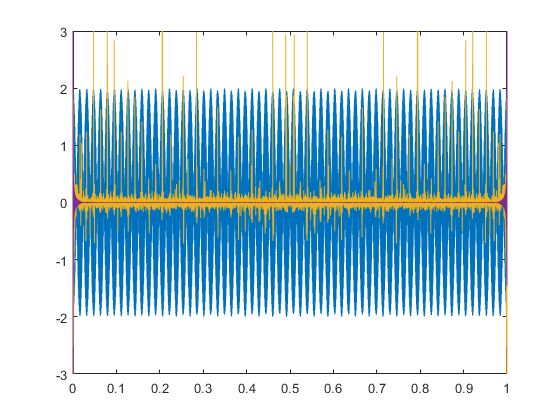


figure
plot(t,csig)
hold on
plot(t,real(ya))
plot(t,real(yc))
plot(t,yf)
ylim([-3 3])